# ACM 11 Week 3: In-class activity

#### Names of all group members: 

Kyle McGraw

In week 2, we saw how the problem of pollutant being leaked into a river can be modeled using the convection-diffusion-reaction equation, and how we can find the steady distribution of the pollutant, $u\left(x\right)$, by discretizing the domain into a grid of n+1 gridpoints, ${\left\lbrace x_i \right\rbrace }_{i=0}^n$. Given the known boundary conditions at the first and last grid point, $u\left(x_0 \right)=u\left(x_n \right)=0$, we have n-1 unknown values of the pollutant at the interior grid points, ${\left\lbrace u\left(x_i \right)\right\rbrace }_{i=1}^{n-1}$. Using the method of finite differences, we can formulate the problem of solving for these $n-1$ unknowns as the following matrix system:

$\mathbf{Au} = -\mathbf{p}$.

We have implemented for you a function, `getAp.m`, that takes the number of grid spaces, n, as an input, and returns $\mathit{\mathbf{A}}$ and $\mathit{\mathbf{p}}$. 

% good habit to always clear all variables and close all figures at start
% of new script
clear; close all 

n = 10;
[A,p] = getAp(n);

**Part 1: **The matrix $\mathit{\mathbf{A}}$ in this PDE application has *tridiagonal* structure. To see this, in the space below, use the command `spy(A)` to have MATLAB visualize the sparsity pattern of $\mathit{\mathbf{A}}$. This command shows where in the matrix there are non-zero entries.

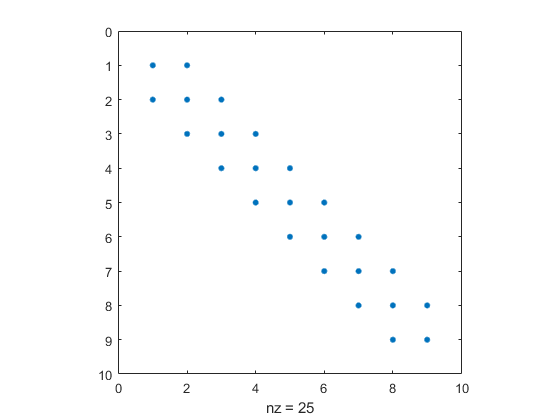

% visualize matrix sparsity here
spy(A)

**Part 2: **In class, we discussed several different algorithms that can be used to solve a linear system, depending on the structure of $\mathit{\mathbf{A}}$: LU decomposition, Cholesky decomposition, tridiagonal matrix algorithm (TDMA), and forward/backward substitution. Which of these algorithms are applicable here? Hint: To check to see if a matrix is symmetric, you can look at `norm(A-A')` - for symmetric matrices this should be close to machine precision (1e-15 or so).

Just the tridiagonal matrix algorithm (TDMA) is applicable because it is tridiagonal.

**Part 3:** While MATLAB backslash is generally what you should use to solve linear systems, in this class we'd like to explore the cost scaling of the different linear solve algorithms. To that end, we have implemented from scratch algorithms for solving via LU decomposition and TDMA. In the code block below, we solve the linear system with our LU and TDMA implementations, and also compare to using backslash and to computing `inv(A)*-p` (although this is generally not a good idea and MATLAB will give you a warning about it).

The code below solves our PDE system with each of these different methods and times the solve for each value of n in `n_vals`. We have initialized the code with just one value to start. In your groups, augment modify the code to try $n=100,200,400,800,1600$ (you might want to try just the first 4 values first and only add the fifth if it seems like your computer can handle it). Timing all solves at all five values of *n* is intended to run in O(5 minutes) or less. Exact run times will vary from machine to machine.

n_vals = [100 200 400 800 1600 3200];     % when you are ready, add more values to this 

times = zeros(length(n_vals),4);

for i = 1:length(n_vals)
    n = n_vals(i)
    [A,p] = getAp(n);
    
    tic
    u = -A\p;
    times(i,1) = toc;
    
    tic
    u = solveLU(A,-p);
    times(i,2) = toc;
    
    tic
    u = solveTDMA(A,-p);
    times(i,3) = toc;
    
    tic
    u = inv(A)*-p;
    times(i,4) = toc;
end

n = 100

n = 200

n = 400

n = 800

n = 1600

n = 3200

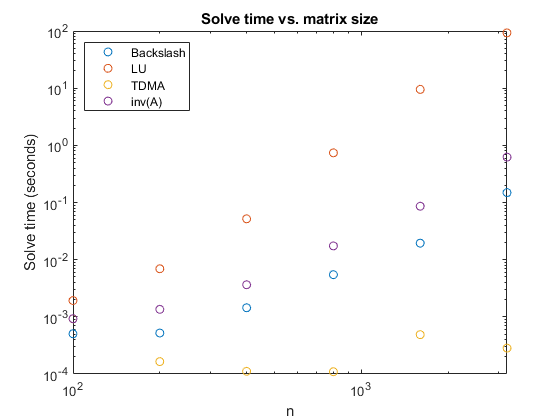


figure;
loglog(n_vals,times,'o')
xlabel('n')
ylabel('Solve time (seconds)')
title('Solve time vs. matrix size')
legend('Backslash','LU','TDMA','inv(A)','Location','NorthWest')

times

times =     0.0005    0.0019    0.0009    0.0009
    0.0005    0.0069    0.0002    0.0014
    0.0014    0.0518    0.0001    0.0036
    0.0055    0.7390    0.0001    0.0174
    0.0194    9.5218    0.0005    0.0861
    0.1490   92.7780    0.0003    0.6220


**Part 4: **In this part we ask you some questions about the scaling of each of the above algorithms and whether it is what you expect. Remember that the expected cost scaling is a big-*n* property, so at smaller matrix sizes you might not see the expected trends. How large n needs to be to see the expected trends depends somewhat on your machine.

**4a:** At large *n*, how does the cost of each of the solve types change as the matrix size is doubled?

LU increases by approimately a factor of 10 each time the matrix size doubles, inv(A) increases by approximately 7 times, Backslash increases by approximately 7 times, and TDMA doesn't seem to increase.

**4b:** Recall that for solving PDEs, the accuracy of the spatial discretization increases as the number of grid points increases, leading to a bigger matrix. If we want to decrease the PDE spatial discretization error by a factor of 100, how much should we increase *n*? How much does the solve time increase as a result if the PDE stencil results in a tridiagonal matrix? How much would the solve time increase if the PDE stencil resulted in a more general dense matrix?

Depending if its a first or second order scheme, error scales as x or x^2, so we will need 10 or 100 times n. Solve time increases by nearly 100% according to our simulations as it takes almost constant time.